% 1. Завантаження зображень
originalImage  = imread('cameraman.tif');
myImage  = imread('hero.jpg');

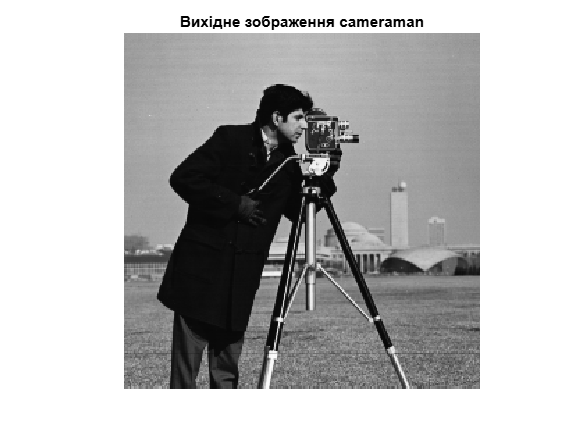

% 2. Відображення вихідного зображення з бібліотеки матлаб
figure;
imshow(originalImage);
title('Вихідне зображення cameraman');

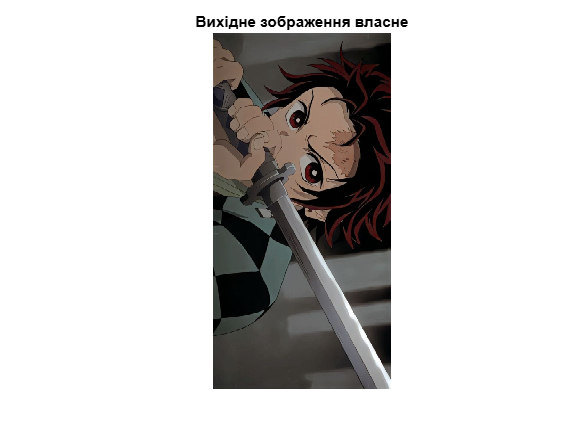

% 2. Відображення вихідного зображення власного
imshow(myImage);
title('Вихідне зображення власне');

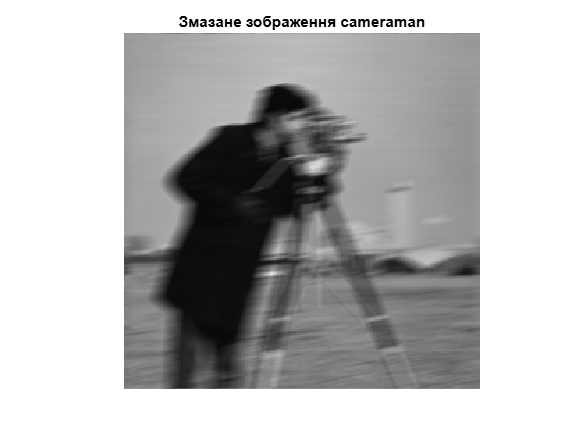

% 3. Перекручення зображення (змазання)
LEN = 15;    
THETA = 10;  
PSF = fspecial('motion', LEN, THETA);
blurred1 = imfilter(originalImage, PSF, 'conv', 'circular');
imshow(blurred1);
title('Змазане зображення cameraman');

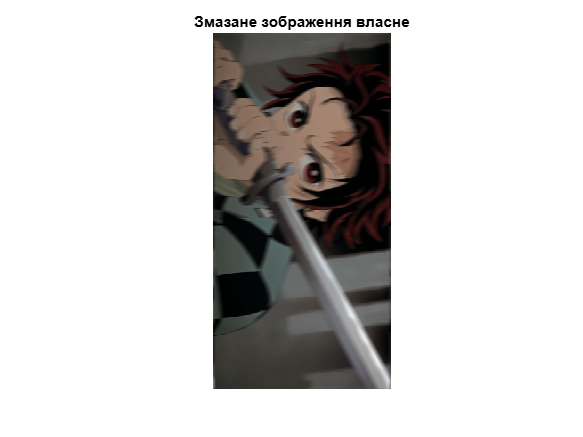

LEN = 20;
THETA = 5;
PSF2 = fspecial('motion', LEN, THETA);
blurred2 = imfilter(myImage, PSF2, 'conv', 'circular');
imshow(blurred2);
title('Змазане зображення власне');

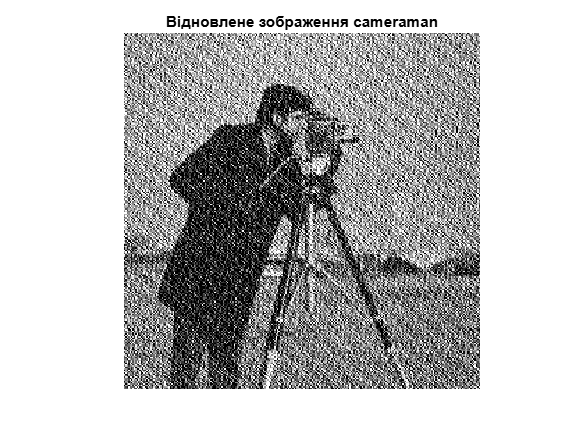

% 5. Відновлення зображення без шуму
SNR = 0; % Відсутність шуму
restoredImage1 = deconvwnr(blurred1, PSF, SNR);
imshow(restoredImage1);
title('Відновлене зображення cameraman');

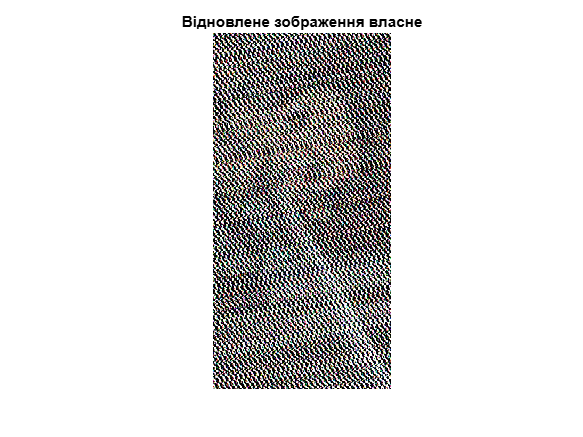

SNR = 0; % Відсутність шуму
restoredImage2 = deconvwnr(blurred2, PSF, SNR);
imshow(restoredImage2);
title('Відновлене зображення власне');

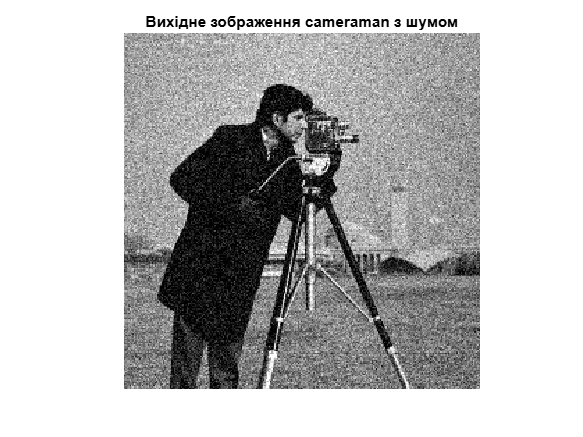

 % 7. Додавання шуму
noisyOriginal  = imnoise(originalImage,'gaussian');
imshow(noisyOriginal );
title('Вихідне зображення cameraman з шумом');

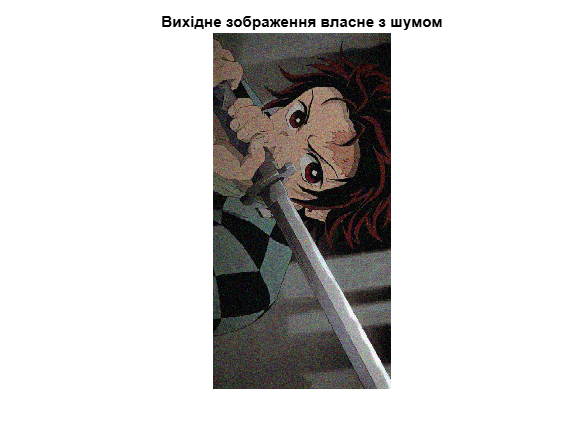

noisyMy  = imnoise(myImage,'gaussian');
imshow(noisyMy );
title('Вихідне зображення власне з шумом');

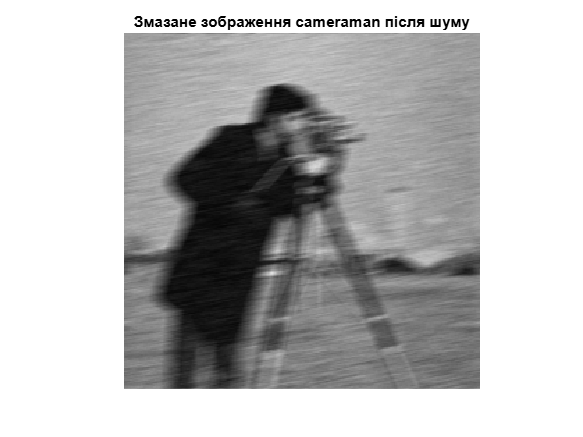

 % Відображення результатів із шумом
blurred3 = imfilter(noisyOriginal , PSF, 'conv', 'circular');
imshow(blurred3);
title('Змазане зображення cameraman після шуму');

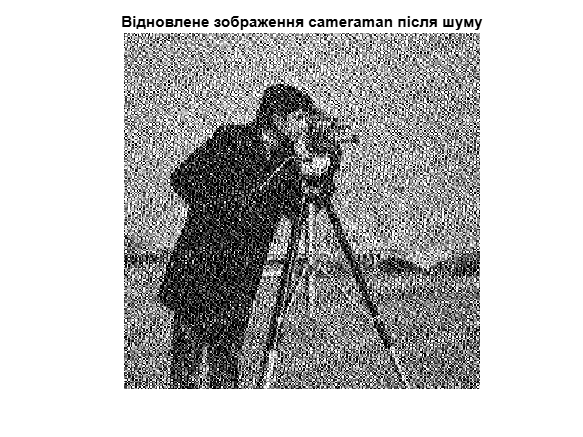

restoredNoisyOriginal  = deconvwnr(blurred3, PSF, 0);
imshow(restoredNoisyOriginal );
title('Відновлене зображення cameraman після шуму');

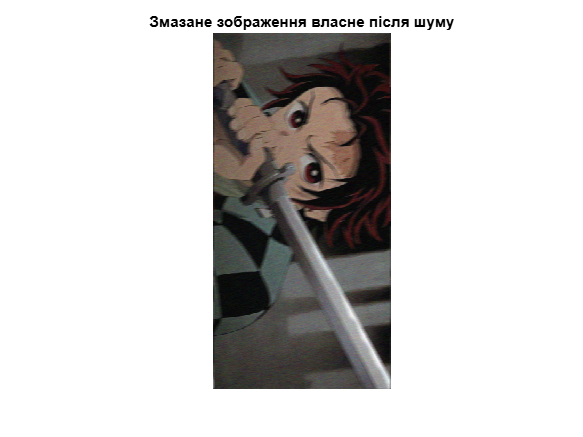

 % Відображення результатів із шумом
blurred4 = imfilter(noisyMy , PSF, 'conv', 'circular');
imshow(blurred4);
title('Змазане зображення власне після шуму');

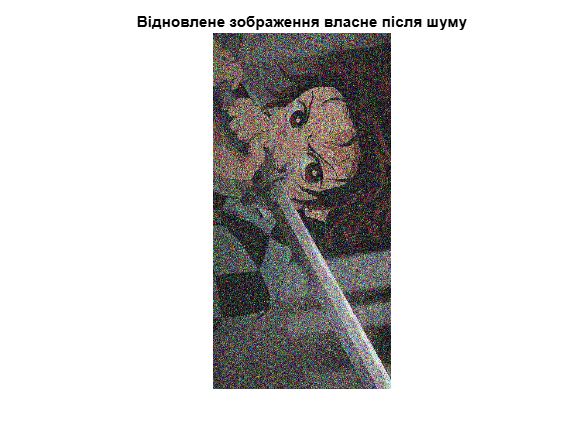

restoredNoisyMy  = deconvwnr(blurred4, PSF, 0);
imshow(restoredNoisyMy );
title('Відновлене зображення власне після шуму');